## Taller 11 - Ecuaciones diferenciales

### Invasión Zombie

**Estudiante**: Cristian Miguel Gómez Salazar

**C.C:** 1003402002

**ID:** 1000245419

### Introducción

Las ecuaciones diferenciales permiten el análisis y predicción de situaciones y comportamientos de sistemas dinámicos simples y complejos con el objetivo de tomar decisiones a través de modelos matemáticos que afectan al sistema en acción. 

El modelo SIRV es, dentro de la gran diversidad de modelos, un modelo que permite el estudio de la propagación y control de epidemias, pandemias y todo lo relacionado con cualquier propagación de virus o bacterias así como la toma de medidas de precaución para los mismos. 

A través del presente taller se abordará el modelo matemático previamente esbozado con el objetivo de llegar a una solución numérica mediante el uso de Matlab y conceptos de métodos numéricos como lo es el de Runge-Kutta.

### Modelo matemático

Se propone el siguiente modelo matemático: 


$$\begin{array}{l}
\frac{\textrm{ds}}{\textrm{dt}}=-\beta *S\left(t\right)*I\left(t\right)-\delta *S\left(t\right)\\
\frac{\textrm{di}}{\textrm{dt}}=\beta *I\left(t\right)*S\left(t\right)-\gamma \;I\left(t\right)\\
\frac{\textrm{dr}}{\textrm{dt}}=\gamma \;I\left(t\right)\\
\frac{\textrm{dv}}{\textrm{dt}}=\delta *S\left(t\right)
\end{array}$$


- S(t) = Porcentaje de personas susceptibles (pueden contraer la enfermedad).

- I(t) = Porcentaje de personas infectadas.

- R(t) = Porcentajes de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes).

- V(t) = Porcentaje de personas vacunadas.

Adicionalmente, se tiene la siguiente información: 

- $\beta$ = Tasa de transmisión.

- $\gamma$= Tasa de recuperación y aislamiento.

-  $\delta$ = Tasa de vacunación. 

Se parte del supuesto de una población cerrada definida de la siguiente manera:


$$P=S\left(t\right)+I\left(t\right)+R\left(t\right)+V\left(t\right)$$


**1.**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

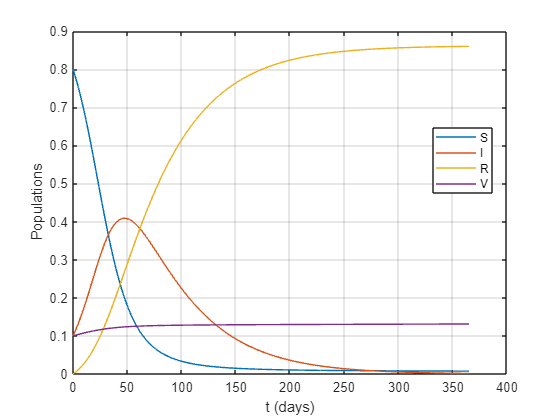

syms S(t) I(t) R(t) V(t)

%Constants
beta = 0.1;
gamma  = 0.02;
delta = 0.001;

%Math model
F1 = -beta*S*I - delta*S; 
F2 = beta*I*S - gamma*I;
F3 = gamma*I;
F4 = delta*S;

%OdeFunction
f = odeFunction([F1 F2 F3 F4],[S I R V]);

%h (time lapse)
Th = 1;

%Time info
ti = 0;
tf = 365;
tspan = ti:Th:tf;

%Initial conditions
    %  S   I  R  V
Ic = [0.8 0.1 0 0.1];
[t1,x1] = ode45(f,tspan,Ic); 

%graph functions
figure
plot(t1,x1)
xlabel('t (days)')
ylabel('Populations')
grid on
legend({'S','I','R','V'}, 'Location','Best')

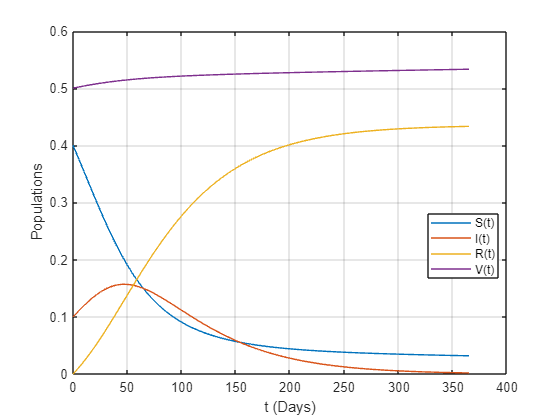

%Changing V(t) initial condition

v0 = 0.5; 
IcV = [0.9-v0  0.1  0  v0]; 
[t2,x2] = ode45(f,tspan,IcV);
plot(t2,x2)
xlabel('t (Days)')
ylabel('Populations')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

#### Análisis particular

A partir de los gráficos previamente obtenidos y variando el valor de vacunados V(t) se observa una reducción considerable en el porcentaje o cantidad de personas tanto suceptibles como infectadas y un aumento en los individuos recuperados respecto a la primera gráfica, lo cual repercute de manera positiva en la población disminuyendo la infección dada por el virus o ente patógeno.

**2. **

Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

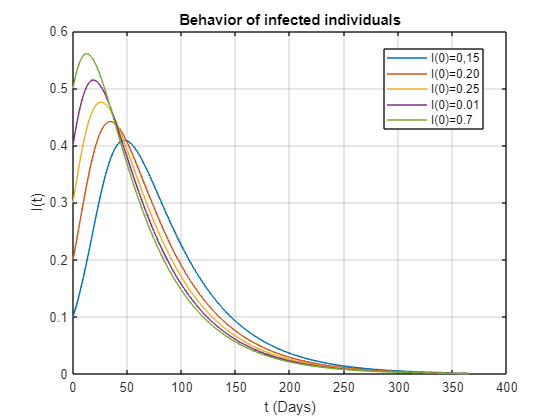

syms S(t) I(t) R(t) V(t)

%Constants
beta = 0.1;
gamma  = 0.02;
delta = 0.001;

%Math model
F1 = -beta*S*I - delta*S; 
F2 = beta*I*S - gamma*I;
F3 = gamma*I;
F4 = delta*S;

%OdeFunction
f = odeFunction([F1 F2 F3 F4],[S I R V]);

%Time info
tstep = 1;
ti = 0;
tf = 365;
tspan = ti:tstep:tf;

%Increasing I(t) values. 
% I increases, S decreases. the sum must be == 1. 

%       S      I   R   V
Ic1 = [0.8   0.1   0  0.1]; 
Ic2 = [0.7   0.20  0  0.1]; 
Ic3 = [0.6   0.3   0  0.1];
Ic4 = [0.5   0.4   0  0.1]; 
Ic5 = [0.4   0.5   0  0.1]; 

%initial conditions for equations
[t1,x1] = ode45(f,tspan,Ic1);
[t2,x2] = ode45(f,tspan,Ic2);
[t3,x3] = ode45(f,tspan,Ic3);
[t4,x4] = ode45(f,tspan,Ic4);
[t5,x5] = ode45(f,tspan,Ic5);

%Ploting on time
plot(t1,x1(:,2), t2,x2(:,2), t3,x3(:,2), t4,x4(:,2), t5,x5(:,2))
title('Behavior of infected individuals')
xlabel('t (Days)')
ylabel('I(t)')
grid on
legend({'I(0)=0,15','I(0)=0.20','I(0)=0.25','I(0)=0.01','I(0)=0.7'}, 'location', 'Best')

#### Análisis particular

Para el presente caso, se aumenta la cantidad de infectados y se varía la cantidad de personas suceptibles, pero dejando las personas recuperadas y vacunadas de manera constante buscando cumplir la condición de que la población es constante y $P=1$, de lo cual se observa un comportamiendo que decae tan rápido como infectados haya, pero si, de lo contrario, se tiene una cantidad de infectados mucho menor la cantidad de personas suceptibles será mayor por lo que la trasnmisión del virus en el tiempo será más prolongada y tardará mucho más en desaparecer.

**3.**

Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

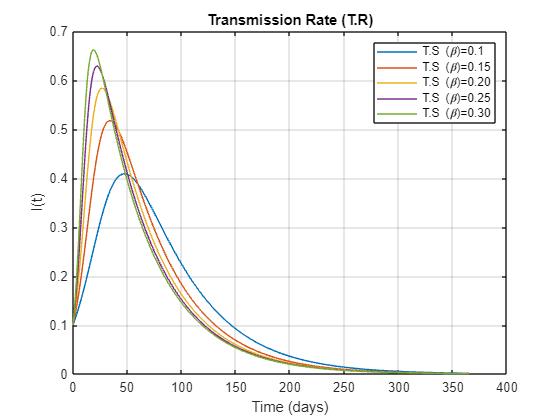

syms s(t) i(t) r(t) v(t)

% Parameters
beta=0.1; 
delta=0.001; 
gamma=0.02;

% Counter for cycle
counter = 1;

% Differential equations
F1=-beta*s*i-delta*s; 
F2=beta*s*i-gamma*i; 
F3=gamma*i; 
F4=delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);

% Initial conditions
                     % S   I  R  V
initial_conditions = [0.8 0.1 0 0.1];

% Time parameters
tstep = 1.0;  
ti = 0;  
tf = 365; 
time_span = ti:tstep:tf;

% Solve the system of ODEs
[time, output] = ode45(f, time_span, initial_conditions);

% Plotting
figure
plot(time, output(:, 2))
grid on
xlabel("Time (days)")
ylabel("Population groups")
hold on

% Increasing transmission rates
while counter < 5
    counter = counter + 1;
    
    % Increasign the transmission rate value
    beta = beta+0.05;
    
    % Update the diff. eq. with the new beta.
    F1=-beta*s*i-delta*s; 
    F2=beta*s*i-gamma*i; 
    F3=gamma*i; 
    F4=delta*s;
    f=odeFunction([F1 F2 F3 F4],[s i r v]);

    % Solve the system of ODEs with the updated transmission rate
    [time, output] = ode45(f, time_span, initial_conditions);

    % Plotting
    plot(time, output(:, 2))
    grid on
    title('Transmission Rate (T.R)')
    xlabel("Time (days)")
    ylabel("I(t)")
    hold on
end
legend("T.S (\beta)=0.1", "T.S (\beta)=0.15", "T.S (\beta)=0.20", "T.S (\beta)=0.25", "T.S (\beta)=0.30", 'location', 'northeast')

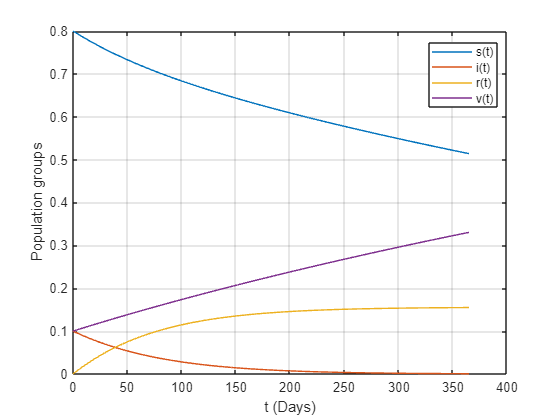


%Giving to beta a value of 0.01 
beta = 0.01; 
gamma = 0.02; 
delta = 0.001;

%Diff equations
f1 = -beta*s*i - delta*s;
f2 = beta*s*i - gamma*i;
f3 = gamma*i; 
f4 = delta*s;
f = odeFunction([f1 f2 f3 f4],[s i r v]);

%Init conditions
Ic = [0.8 0.1 0 0.1];
[t1,x1] = ode45(f,time_span,Ic);

%Plotting
figure
plot(t1,x1)
xlabel('t (Days)')
ylabel('Population groups')
grid on
legend({'s(t)','i(t)','r(t)','v(t)'}, 'Location','Best')

#### Análisis particular

De acuerdo a lo anterior, se puede observar en la primera gráfica que se da un comportamiento que no contribuye a que no se de la pandemia ya que la tasa de trasnmisión (beta) está en aumento, pero con una reducción de esta a un valor de 0.01, se observa en el gráfico 2 un comportamiento en los cuales las personas recuperadas tienden a estabilizarse conforme los infectados llegan a 0 mientras que los vacunados ascienden en porcentaje y, por ende, las personas suceptibles disminuyen.

**4.**

Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

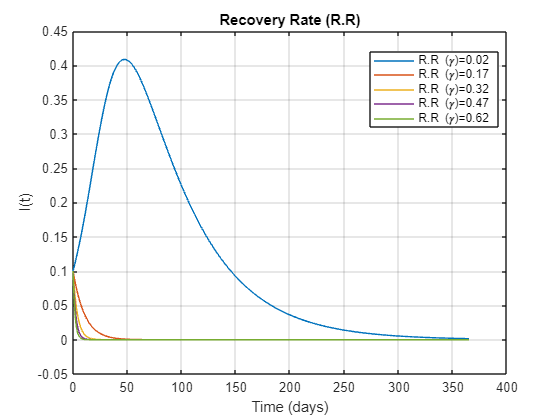

syms s(t) i(t) r(t) v(t)

% Parameters
beta=0.1; 
delta=0.001; 
gamma=0.02;

% Counter for cycle
counter = 1;

% Differential equations
F1=-beta*s*i-delta*s; 
F2=beta*s*i-gamma*i; 
F3=gamma*i; 
F4=delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);

% Initial conditions
                     % S   I  R  V
initial_conditions = [0.8 0.1 0 0.1];

% Time parameters
tstep = 1.0;  
ti = 0;  
tf = 365; 
time_span = ti:tstep:tf;

% Solve the system of ODEs
[time, output] = ode45(f, time_span, initial_conditions);

% Plotting
figure
plot(time, output(:, 2))
grid on
xlabel("Time (days)")
ylabel("Population groups")
hold on

% Increasing recovery rate
while counter < 5
    counter = counter + 1;
    
    % Increasign the recovery rate value
    gamma = gamma+0.15;
    
    % Update the diff. eq. with the new gamma.
    F1=-beta*s*i-delta*s; 
    F2=beta*s*i-gamma*i; 
    F3=gamma*i; 
    F4=delta*s;
    f=odeFunction([F1 F2 F3 F4],[s i r v]);

    % Solve the system of ODEs with the updated transmission rate
    [time, output] = ode45(f, time_span, initial_conditions);

    % Plotting
    plot(time, output(:, 2))
    grid on
    title('Recovery Rate (R.R)')
    xlabel("Time (days)")
    ylabel("I(t)")
    hold on
end

legend("R.R (\gamma)=0.02", "R.R (\gamma)=0.17", "R.R (\gamma)=0.32", "R.R (\gamma)=0.47", "R.R (\gamma)=0.62", 'location', 'Best')

#### **Análisis particular**

A través del anterior estudio, se puede observar como mientras la tasa de recuperación y aislamiento aumenta hasta un valor de 0.62 aproximadamente, los grupos de poblaciones de infectados, vacunados y recuperados aumentan considerablemente hasta que la población se recupera por completa mientras que los infectados disminuyen casi de inmeditato. Esto es de vital importancia ya que, a través de la proporcionalidad de aumento de la tasa de recuperación y el aumento de los grupos de población sanos se puede ver la importancia de la importancia del cuidado personal frente a patógenos de transmisión por contacto.   

**5.**

Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

syms s(t) i(t) r(t) v(t)

% Parameters
beta=0.1; 
delta=0; 
gamma=0.02;

% Counter for cycle
counter = 1;

% Differential equations
F1=-beta*s*i-delta*s; 
F2=beta*s*i-gamma*i; 
F3=gamma*i; 
F4=delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);

% Initial conditions
                     % S   I  R  V
initial_conditions = [0.8 0.1 0 0.1];

% Time parameters
tstep = 1.0;  
ti = 0;  
tf = 365; 
time_span = ti:tstep:tf;

% Solve the system of ODEs
[time, output] = ode45(f, time_span, initial_conditions);

% Plotting
figure
plot(time, output(:, 2))
grid on
xlabel("Time (days)")
ylabel("Population groups")
hold on

% Increasing vaccination rate
while counter < 5
    counter = counter + 1;

    if counter == 3 || counter == 4 || counter == 5
        delta  = delta + 0.2
    else
        delta = delta + 0.032;
    end
    
    
    % Update the diff. eq. with the new delta.
    F1=-beta*s*i-delta*s; 
    F2=beta*s*i-gamma*i; 
    F3=gamma*i; 
    F4=delta*s;
    f=odeFunction([F1 F2 F3 F4],[s i r v]);

    % Solve the system of ODEs with the updated vaccination rate
    [time, output] = ode45(f, time_span, initial_conditions);

    % Plotting
    plot(time, output(:, 2))
    grid on
    title('Vaccination Rate (V.R)')
    xlabel("Time (days)")
    ylabel("I(t)")
    hold on
end

delta =    0.232000000000000


delta =    0.432000000000000


delta =    0.632000000000000


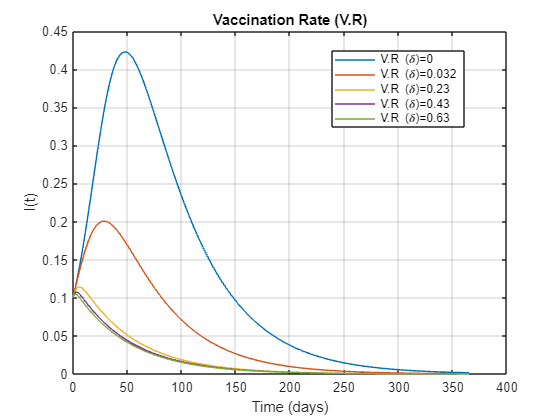


legend("V.R (\delta)=0", "V.R (\delta)=0.032", "V.R (\delta)=0.23", "V.R (\delta)=0.43", "V.R (\delta)=0.63", 'location', 'Best')

#### Análisis particular

Para el caso anterior se tiene una disminución de individuos infectados cuanto mayor es la tasa de vacunación cuya repercución es de manera positiva ya que el grupo de población de personas recuperadas aumenta totalmente. Adicionalmente, se tiene un 20% de individuos infectados con una tasa de vacunación de 0.032; sin embargo, se puede observar que lo ideal sería tener una tasa de vacunación lo suficientemente alta con el objetivo de que la población completa sane. 

### **Análisis general:**

Mediante el uso de funciones de Matlab y el uso del lenguaje mismo, se llegó a soluciones numéricas de factores que influyen directamente en el modelo matemático SIRV el cual permite el control de contagio por patógenos, permitiendo predecir comportamientos de las poblaciones implicadas y la toma de decisiones sobre las mismas cuya influencia afecta a la población total. De igual manera, se pudo predecir el comportamiento de los individuos infectados respecto a las otros grupos de población mientras las tasas de aislamiento, transmisión y vacunación variaban consigo.

### Conclusiones: 

A través del presente taller se logró, mediante el modelo matemático SIRV, realizar un análisis de cómo los parámetros tanto variables como constantes afectan el comportamiento y la integridad de una población, lo cual deja en claro la importancia y utilidad de las ecuaciones diferenciales para el estudio de fenómenos de cualquier tipo (modelo epidemiológico en este caso). Adicionalmente, se evidencia la manera en cómo se puede predecir comportamientos y magnitudes de los parámetros presentes en el modelo, permitiendo una mejor toma de desiciones frente a los diversos casos que se presentan.